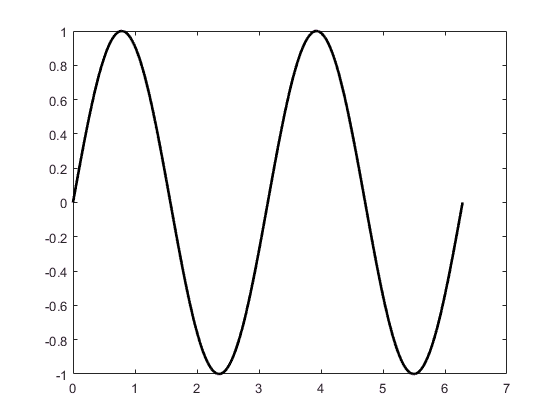

% Logical Indexing:
x = linspace(0,2*pi,1000);
y = sin(2*x);
plot(x,y,'k-','linew',2);
hold on

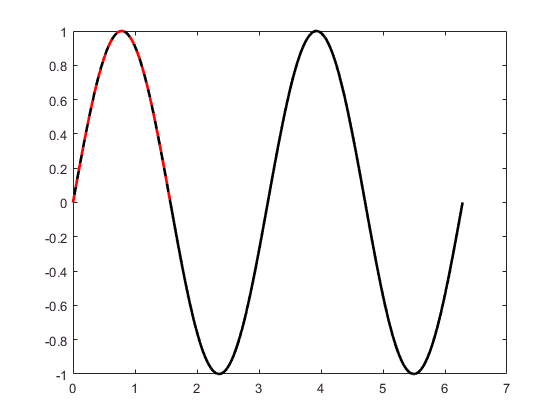

plot(x(x<pi/2),y(x<pi/2),'r--','linew',2)

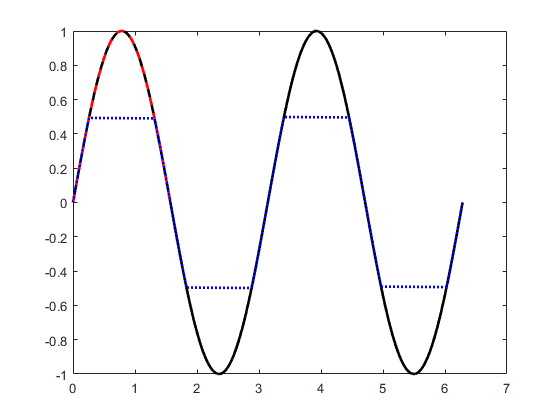

plot(x((y > -0.5)  & (y < 0.5)), y((y > -0.5)  & (y < 0.5)),'b:','linew',2)

% row-wise vs col-wise accessing
mat = ones(1000,1000); n = 1e6;
tic();
for i = 1:n, vec = mat(1,:); end
toc()

Elapsed time is 16.317489 seconds.



tic();
for i = 1:n, vec = mat(:,1); end
toc()

Elapsed time is 2.183588 seconds.


A = 1:18;
B = reshape(A,3,3,2);
C = B(:,1,:)

C = 
(:,:,1) =

     1
     2
     3


(:,:,2) =

    10
    11
    12


D = C(1:2:end)

D =      1     3    11


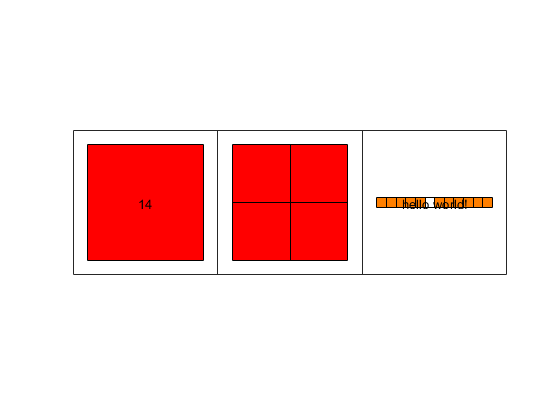

c = {14, [1,2;5,10], 'hello world!'};
cellplot(c)

c_num = [84.5, 91.0, 98.0, 80.5, 99.0, 100.0, 88.0];
s_data_1 = whos('c_num')

s_data_1 = struct with fields:
          name: 'c_num'
          size: [1 7]
         bytes: 56
         class: 'double'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


s_data_1.bytes

ans = 56

c = {84.5, 91.0, 98.0, 80.5, 99.0};
s_data = whos('c')

s_data = struct with fields:
          name: 'c'
          size: [1 5]
         bytes: 600
         class: 'cell'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


s_data.bytes

ans = 600